# Lecture 4 Demo: Visualization of Complex Exponential and Sinusoidal Signals

## CT  Periodic complex exponential signal

###                    
$$x(t)=e^{j2\pi t} $$


###                            
$$= cos(2\pi t) + j \sin(2\pi t), \; \; 0 \leq t  \leq 4$$


### **Use plot3 to make a 3-dimensional plot of the complex signal versus time.   Rotate the plot to see the real and imaginary parts.**

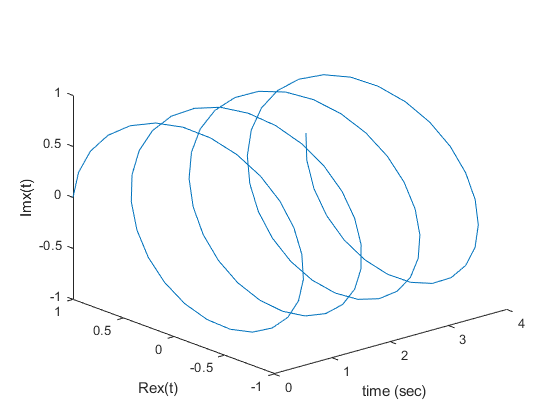

t=linspace(0,4,100);
re=cos(2*pi*t);
im=sin(2*pi*t);
plot3(t,re,im);
xlabel('time (sec)');
ylabel('Re{x(t)}');
zlabel('Im{x(t)}');

## ** CT Decreasing general complex exponential signal**

###                
$$x(t)=e^{(-1+j2\pi) t} $$


###                       
$$=e^{-t}\cos(2\pi t) + je^{-t}\sin(2\pi t), \; \; 0 \leq t \leq 4$$


### **Use plot3 to make a 3-dimensional plot of the complex signal versus time.   Rotate the plot to see the real and imaginary parts.**

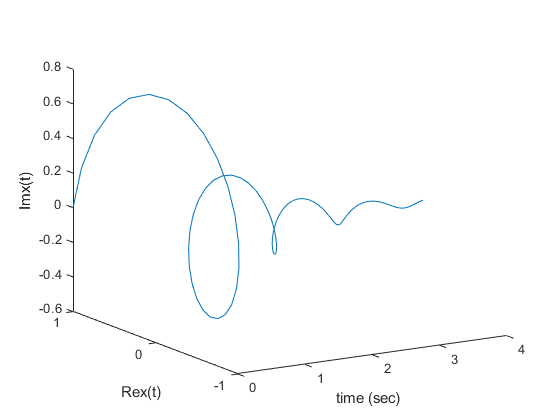

t=linspace(0,4,100);
re=exp(-t).*cos(2*pi*t);
im=exp(-t).*sin(2*pi*t);
plot3(t,re,im);
xlabel('time (sec)');
ylabel('Re{x(t)}');
zlabel('Im{x(t)}');

## **CT   Increasing general complex exponential signal**

###                
$$x(t)=e^{(1+j2\pi) t} $$


###                       
$$=e^{t}\cos(2\pi t) + je^{t}\sin(2\pi t), \; \; 0 \leq t \leq 4$$


### **Use plot3 to make a 3-dimensional plot of the complex signal versus time.   Rotate the plot to see the real and imaginary parts.**

t=linspace(0,4,100);
re=exp(t).*cos(2*pi*t);
im=exp(t).*sin(2*pi*t);
plot3(t,re,im);
xlabel('time (sec)');
ylabel('Re{x(t)}');
zlabel('Im{x(t)}');

## DT and CT  sinusoidal signals

###             
$$x[n]=\sin(2\pi n/8), \; \; 0 \leq n \leq 64$$


###             
$$x(t)=\sin(2\pi t/8), \; \; 0 \leq t \leq 64$$


### **Use stem and plot to create a plot showing  this pair of DT and CT  sinusoids.  **

### **Are they periodic? If so, what  is the fundamental period of each of  the signals?**

$x[n]$has fundamental period $N_0=8 $

$x(t)$ has  fundamental period $T_0=8 $

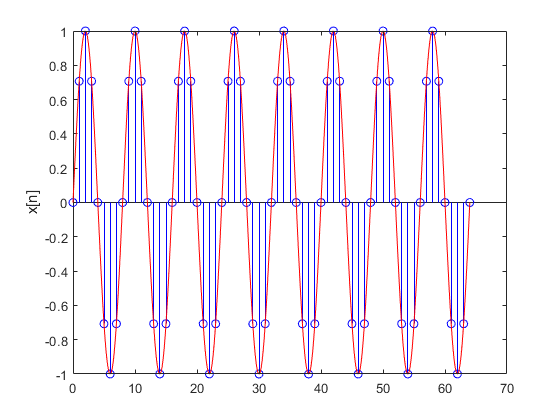

n=0:64;
x=sin(2*pi*n/8);
stem(n,x,'b');
ylabel('x[n]')
hold on
%
t=0:0.1:64;
xt=sin(2*pi*t/8);
plot(t,xt,'r')
hold off

## Another pair of DT and CT sinusoidal signals

###             
$$y[n]=\sin(8\pi n/31), \; \; 0 \leq n \leq 64$$


###             
$$y(t)=\sin(8\pi t/31), \; \; 0 \leq t \leq 64$$


### **Use stem and plot to create a plot showing  this pair of DT and CT  sinusoids.  **

### **Are they periodic? If so, what  is the fundamental period of each of  the signals?**

$x[n]$ has fundamental period $N_0=31$ 

$x(t)$ has  fundamental period $T_0=31/4=7.75$ 

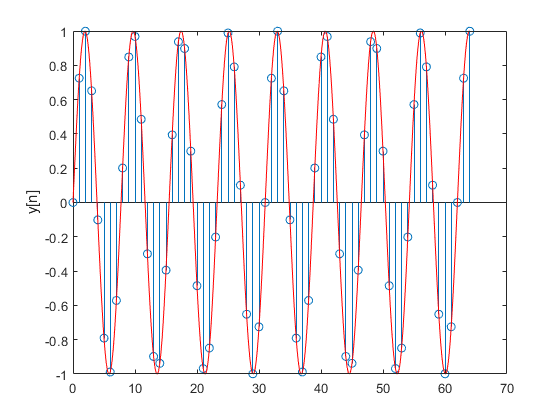

n=0:64;
y=sin(8*pi*n/31);
stem(n,y);
ylabel('y[n]')
hold on
%
t=0:0.1:64;
yt=sin(8*pi*t/31);
plot(t,yt,'r')
hold off

## Yet another pair of DT and CT sinusoidal signals

### 
$$z[n]=\sin(3 n/4), \; \; 0 \leq n \leq 64$$


### 
$$z(t)=\sin(3 t/4), \; \; 0 \leq t \leq 64$$


### **Use stem and plot to create a plot showing  this pair of DT and CT  sinusoids.  **

### **Are they periodic? If so, what  is the fundamental period of each of  the signals?**

$x[n]$ is aperiodic.

$x(t)$ has  fundamental period $T_0=8\pi/3 \approx 8.3775$

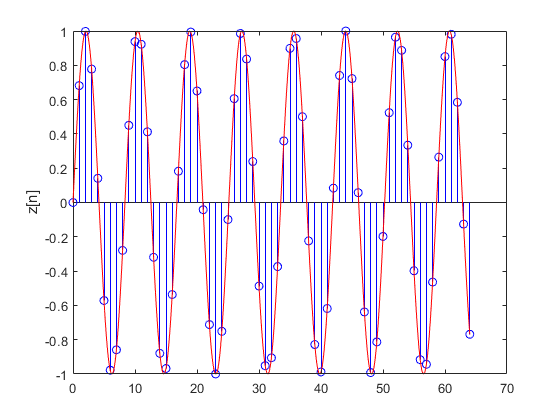

n=0:64;
z=sin(3*n/4);
stem(n,z,'b');
ylabel('z[n]')
hold on
%
t=0:0.1:64;
zt=sin(3*t/4);
plot(t,zt,'r')
hold off